# МЕТОДЫ ОПТИМИЗАЦИИ

### Семинар 10. Линейная регрессия

Краткое резюме по предыдущим семинарам, посвященным линейной регрессии.

Сформулируем еще раз задачу регрессии, представить вектор зависимой переменнной в виде линейной комбинации векторов предикторов :


$$\vec{Y} = X\vec{\beta} +\vec{\epsilon}$$


$X$ - матрица независимых переменных (предикторов),

$\vec{\beta}$ - это истинные значения параметров модели, 

$\vec{Y}$ - зависимая переменная (опять вектор, матрицей она стала не на долго)

 $\vec{\epsilon}$ - случайный вектор ошибки.

 $\hat{\vec{Y}}$ - это значения зависимой переменной, рассчитанные в рамках нашей модели. 

$\vec{b}=(X^TX)^{-1}X^T\vec{Y}$ - обучение модели.

$\hat{\vec{Y}}=HY=X(X^TX)^{-1}X^T\vec{Y}=X\vec{b}$, где $\vec{b}$ - вектор параметров регрессии.

Так как пространство ошибки ортогонально пространству столбцов матрицы предикторов, то скалярное произведение ошибки на  $\hat{\vec{Y}}$ будет равно нулю:


$$\vec{\epsilon}^T\hat{\vec{Y}}=0$$


Понятно, что Y в шляпе включает как ошибку модели, так и ошибку случайности.

### Оценка качества регресии

Для оценки качества регрессии применяется $R^2$ статистика:


$$R^2=\frac{
 [\hat{\vec{Y}}-\vec{I}\overline{Y}]^T[\hat{\vec{Y}}-\vec{I}\overline{Y}] } { [\vec{Y}-\vec{I}\overline{Y}]^T[\vec{Y}-\vec{I}\overline{Y}]}$$


Данный коэффициент хараткеризует долю вариации зависимой переменной в обучающей выборке, которая описывается вариацией регрессионной модели. 

Если, например, мы имеем четыре точки и хотим их описать полиномом третьей степени (матрица предикторов$X=[\vec{I},\vec{X},\vec{X}^2, \vec{X}^3]$, то есть, количество точек равно порядку полинома +1, задача регрессии решается однозначно, все матрицы становятся квадратными, псевдообратная матрица  - обратной, ошибка равной нулю и т.д., то есть $\hat{\vec{Y}}=\vec{Y}$ в этом случае$R^2$=1. 

Если предполагать, что ошибка для каждой точки независима, и все они получены из некоторого распределения с дисперсией $\sigma$, тогда: 


$$Cov(\vec{\epsilon})=I\sigma^2$$


Матрица ковариации параметров модели:


$$Cov(\vec{b})=(X^TX)^{-1}\sigma^2$$


Соотвественно, когда мы используем обученную модель для предсказаний, то есть у нас есть новая матрица предикторов $X_1$ и мы хотим предсказать какие значения $\vec{Y_1}$, то :


$$\vec{Y_1}=X_1\vec{b}$$



$$Cov[\vec{Y_1}]=X_1^TCov(\vec{b})X_1$$


Эта формула следует из  того, что $\mathbb{E}[\vec{b}]=\vec{\beta}$, => $\mathbb{E}[X_1\vec{b}] = X_1\mathbb{E}[\vec{b}]$, тогда:


$$Cov(\vec{Y_1})=Cov[X_1\vec{b}]=[X_1\vec{b}-\mathbb{E}[X_1\vec{b}]][X_1\vec{b}-\mathbb{E}[X_1\vec{b}]]^T=X_1(\vec{b}-\vec{\beta})(\vec{b}-\vec{\beta})^TX_1^T=X_1^TCov(\vec{b})X_1$$


Для того, чтобы экспериментально оценить $\sigma^2$ используется квадратиное отклонение предсказанного значения от исходного вектора зависимой переменной обучающей выборки


$$\sigma^2=\frac{\vec{\epsilon}^T\vec{\epsilon}} {N-P}= \frac{(\vec{Y} - \hat{\vec{Y}})^T(\vec{Y} - \hat{\vec{Y}})}{N-P}$$


N-P - число степеней свободы вектора ошибки (оно же рамерность линейного пространства ошибки)

### Число степеней свободы случайного вектора

При расчете матрицы ковариации, квадратичное отклонение нормируется на число степеней свободы


$$Cov(\vec{\Psi})=[\Psi-\overline{\Psi}][\Psi-\overline{\Psi}]^T/df$$


$df$ - число степеней свободы. С точки зрения линейной алгебры число степеней свободы  - это размерность пространства, из которого "набирается" случаный вектор. Например, из общей картины линейной алгебры мы помним, что размерность пространства ошибки регресси равна $N-P$, где $N$ - число координат вектора ошибки, а $P$- число коэффициентов линейной регрессии (ранг матрицы предикторов).

### Принцип максимального правдоподобия

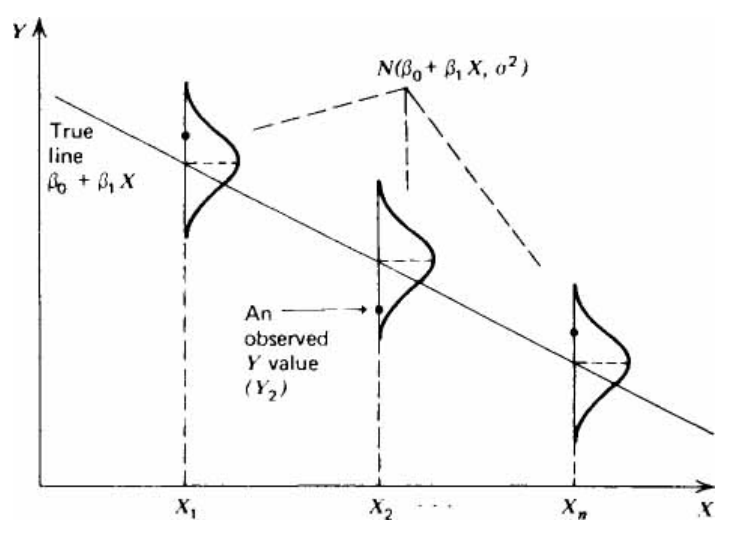


$$\vec{Y} = X\vec{\beta} +\vec{\epsilon}$$


Для каждого наблюдаемого значения Y ошибка берется из одного и того же стандартного распределения , сами габлюдаемые точки соотвественно распределены сог

$ \mathcal{N}(0,1)$ - стандартное нормальное распределение (функция randn)

Чтобы получить переменную, взятую из $\zeta \sim \mathcal{N}(\mu,\sigma^2)$ из переменной, взятой из стандартного распределения $ \eta \sim \mathcal{N}(0,1)$


$$\zeta \sim \mathcal{N}(\mu,\sigma^2) = \mu + \sigma^2 \mathcal{N}(0,1)$$


$\vec{Y} = \vec{\mu_Y} +\vec{\epsilon}$, 

где $\epsilon_i \sim \mathcal{N}(0,\sigma^2)$ - каждая координата вектора ошибки

$\vec{\mu_Y} =X\vec{\beta}$ - вектор средних значений

 $y_i\sim \mathcal{N}(X_{i1}\beta_1 + X_{i2}\beta_2 +...X_{iP}\beta_{P},\sigma^2) $ - то есть каждая координата вектора зависимой переменной  - это случайная величина, поученная из нормального распределения со своим средним значением, но дисперсия для всех одинаковая

Плотность вероятности для конкретной наблюдаемой точки будет:  


$$p(y_i;\mu_i,\sigma)= \frac {1}{\sqrt{2\pi\sigma^2}} e^{ \frac {-(y_i-\mu_i)^2}{2\sigma^2}}$$


Теперь зададимся вопросом, какова вероятность получить тот набор точек, который мы имеем?


$$P(\vec{Y}|\sigma^2) = [\frac {1}{\sqrt{2\pi\sigma^2}}]^N \prod_{i=1}^N e^{-\frac {(y_i-\mu_i)^2}{2\sigma^2}}= [\frac {1}{\sqrt{2\pi\sigma^2}}]^N e^{\frac {-\Sigma_i(y_i-\mu_i)^2}{2\sigma^2}}=[\frac {1}{\sqrt{2\pi\sigma^2}}]^N e^{-\frac {(\vec{Y} -X\vec{\beta})^T(\vec{Y} -X\vec{\beta})  }{2\sigma^2}}$$


Теперь, если рассмотреть данную вероятность как функцию параметров при измеренных значениях случайной величины, то она называется функция правдоподобия (likelihood):


$$\mathcal{L}(\vec{\beta}|\vec{Y})=[\frac {1}{\sqrt{2\pi\sigma^2}}]^N e^{-\frac {(\vec{Y} -X\vec{\beta})^T(\vec{Y} -X\vec{\beta})  }{2\sigma^2}}$$


Что мы отсюда видим:

- Уменьшение показателя экспоненты приводит к увеличению правдоподобия наших данных

- В показатели экспоннеты стоит $(\vec{Y} -X\vec{\beta})^T(\vec{Y} -X\vec{\beta}) =\vec{\epsilon}^T\vec{\epsilon}}$ - то есть максимизация правдоподобия эксвивалентна минимизации квадрата ошибки

- Отсюда можно интуитивно понять что нужно минимизировать, если ошибка для каждой точки получена из распределения с различной дисперсией


$$P(\vec{Y}|\sigma^2) \sim \prod_{i=1}^N e^{-\frac {(y_i-\mu_i)^2}{2\sigma_i^2}}=  e^{\Sigma_i\frac {-(y_i-\mu_i)^2}{2\sigma_i^2}}= e^{\frac{1}{2} \Sigma_i -(\frac{y_i}{\sigma_i}-\frac{\mu_i}{\sigma_i})^2}= e^{- {(\vec{Y'} -X'\vec{\beta})^T(\vec{Y'} -X'\vec{\beta})  }$$


$\vec{\epsilon} => W\vec{\epsilon}$, $W $ - диагональная матрица дисперсий ошибки, $X'$ - матрица предикторов, в которой каждая строка умножена на корень соотвествующего веса, $\vec{Y'}$ - вектор зависимой переменной в которой каждый элемент умножен на вес

Таки мобразом, чтобы учесть веса мы должны:


$$X'=>WX$$



$$Y'=>W\vec{Y}$$


Это дает формулу для линейной регрессии с весами:


$$\vec{b} = (X^TWX)^{-1}X^TWY$$


### Линейная регрессия с весами (weighted regression)

x = sort(rand(10,1));
y = 2 + 3*x + randn(size(x));


% добавляем веса последней точки путем повторения ее значения в выборке
nreps = 43

nreps = 43

% просто повторим одну точку nreps раз
ax = get_next_ax();
plot(ax,[x;1],[y;9],'o');
hold(ax,"on");
plot(ax,[1],[9],'diamond',"MarkerFaceColor","r");
for n = [1,nreps]
    x2 = [x;ones(n,1)];
    y2 = [y;repmat(9,n,1)];
    % and solve
    M2 = [ones(size(x2)),x2];
    coef = M2\y2;
    yhat = M2*coef;
    plot(ax,x2,yhat,'-',"LineWidth",3);
end
hold(ax,"off")
xlim(ax,[0 1.2]);
ylim(ax,[1 10]);
legend(ax,["Данные","Последняя точка", "Все с одним весом", "Вес последней точки="+string(nreps)],"Location","best")
coef

coef =     0.3650
    8.3079


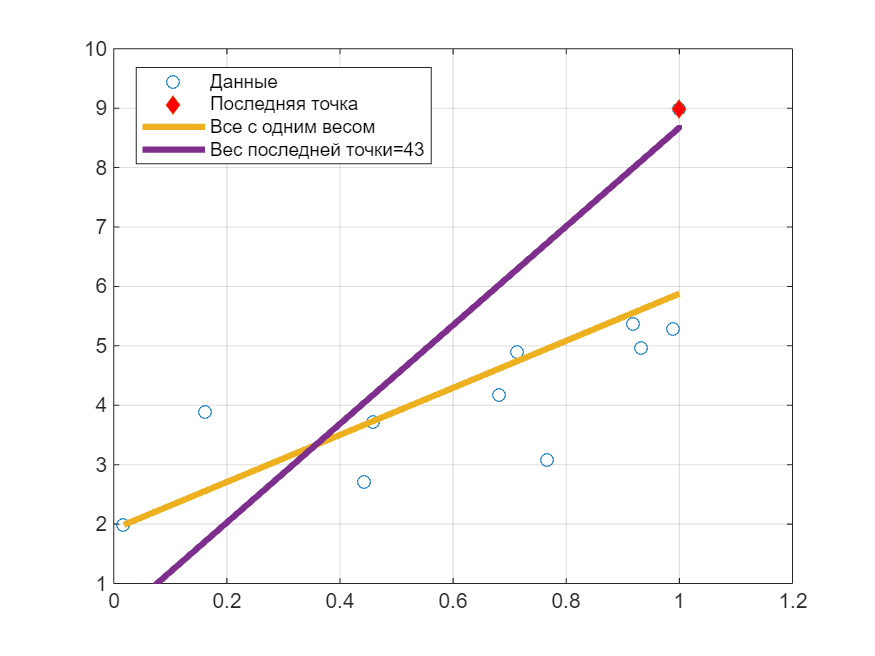

grid(ax,"on")


% как можно сымитировать подобное поведение
x3 = [x;1];
y3 = [y;9];
weights = [ones(size(y));sqrt(nreps)];

M3 = [ones(size(x3)),x3];
% умножем каэдую строку матрицы предикторов на веса и кажд
coef = (diag(weights)*M3)\(weights.*y3)

coef =     0.3650
    8.3079



% взвешенная регрессия делается функцией:
weights = [ones(size(y));nreps];
coef = lscov(M3,y3,weights)

coef =     0.3650
    8.3079


### Локально-взвешенная линейная регрессия (local-weighted regression)

Основная идея локально взвешенной регрессии состоит в том, что мы задаем веса как некоторую функцию от независимых переменных таким образом, чтобы наибольший вес имели те точки, которые лежат в той области, которая представляет для нас наибольший интерес.

В следующем ниже примере мы будем пытаться описать квадратичную зависимость линейной, в качестве весов будет выступать функция:


$$f(x;\mu,\sigma)=\frac{1}{\sqrt{2\pi\sigma}}e^{\frac{(x-\mu)^2}{2\sigma^2}}$$


Она выглядит знакомо и удобна тем, что имеет максимум и два параметра, которыми регулируется ее ширина и положение этого максимума. Таким образом матрица весов будет:


$$W = diag(f(\vec{X}))$$


Таким образом, в окрестности координаты $x=\mu$ точки будут иметь наибольший вес.

Локально взвешенная регрессия сравнивается с классической линейной регрессией.

clearvars
N= 300;
x = randn(N,1);
x=sort(x);
y_measured = 2 + 0.4*x + x.^2 + 0.1*randn(N,1); % истинная модель
Ivect = ones(size(x));
X = [Ivect,x]; % матрица предикторов

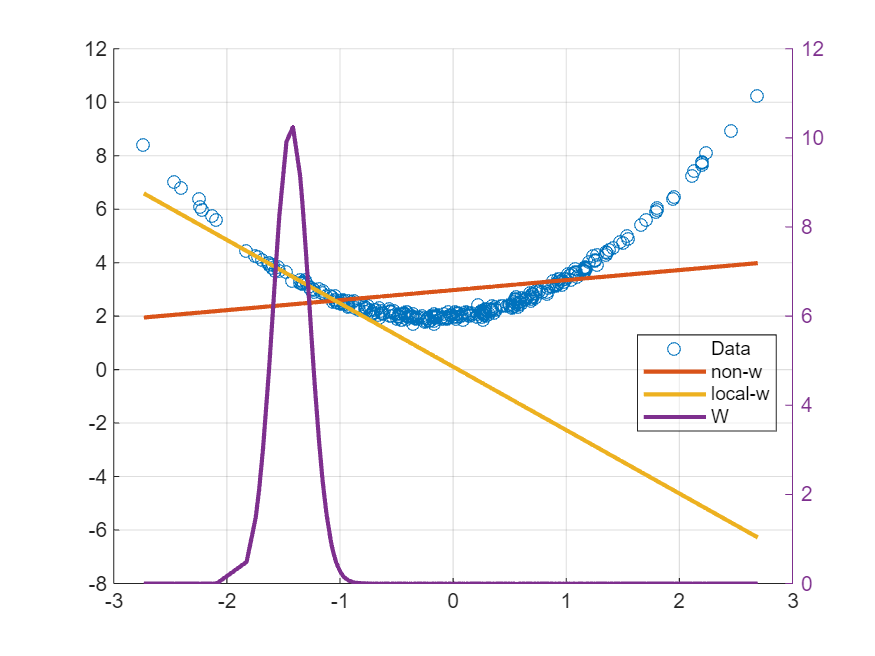


% в качестве весовой функции выберем Гауссову функцию (она имеет два
% параметра, четкий максимум - удобно)
mu = -1.43;sig = 0.16;
weights_function = norm_distribution_function(mu,sig);
weights= weights_function(x);% вектор весов
coeff_unweighted = X\y_measured;
coef_weighted = (diag(weights)*X)\(weights.*y_measured);
ax = get_next_ax();
scatter(ax,x,y_measured);
hold(ax,"on")
plot(ax,x,X*coeff_unweighted,"LineWidth",2);
plot(ax,x,X*coef_weighted,"LineWidth",2);
yyaxis(ax,"right")
plot(x,weights*max(y_measured)/max(weights),"LineWidth",2);
hold(ax,"off")
grid(ax,"on")
legend(ax,["Data", "non-w", "local-w","W"],Location="best",BackgroundAlpha=0.5)

### Robust regression

    Робастная регрессия нужна в сех случаях, когда исходные данные имеют выбросы. Основная идея робастной регрессии состоит в том, чтобы сделать веса обратно пропорциональными (это может быть и некоторая функция, которая стремиться к нулю при увеличении аргумента) ошибкам регрессии, таким образом, стартуя с регрессия с равномерными весами, для которой выбросы будут иметь большой вклад в ошибку регрессии, можно постепенно прийти к регрессии с малыми весами выбросов.

    Данные будут представлять собой достаточно гладкую монотонную кривую, на которой будут отдельные случайные выбросы, выбросы будут иметь не гауссово распределение, поэтому их вклад в ошибку регрессии будет плохо описываться методом наименьших квадратов (см. принцип максимального правдоподобия). Весовая функция будет иметь форму :


$$f(\vec{\epsilon})= exp(-(\mu\vec{\epsilon}/max(\vec{\epsilon})^2)$$


$\mu$ - это параметр. В общем-то, функция может быть любой, главное, чтобы она спадала с ростом аргумента и стремилась в пределе к нулю, а при нулевой ошибке давала единицу, тот же гауссиан подходит.

% пример взят из [1]
clearvars
n = 20;
m = 3;% число выбросов
x = 2*rand(n,1) - 1;
x=sort(x);
y0 = exp(x); % создаются данные с простой монотонной зависимостью
%теперь к ним добавляются точки шума с негаусовой формой распределения  -
%выбросы
noise = randn(m,1)/2;
noise = sign(noise).*abs(noise).^4;
y = y0;
coeff_no_noise = polyfit(x,y0,4)

coeff_no_noise =     0.0463    0.1751    0.4976    0.9984    1.0001


y(randi(n,[m 1]))= y(randi(n,[m 1])) + noise; % добавляем шумы к m случайным точкам


iterations = 3;% число итераций
% далее будем итерационно менять веса обратной пропорционально величине
% ошибки
% исходно все веса равны единице
mu = 4.93

mu = 4.9300

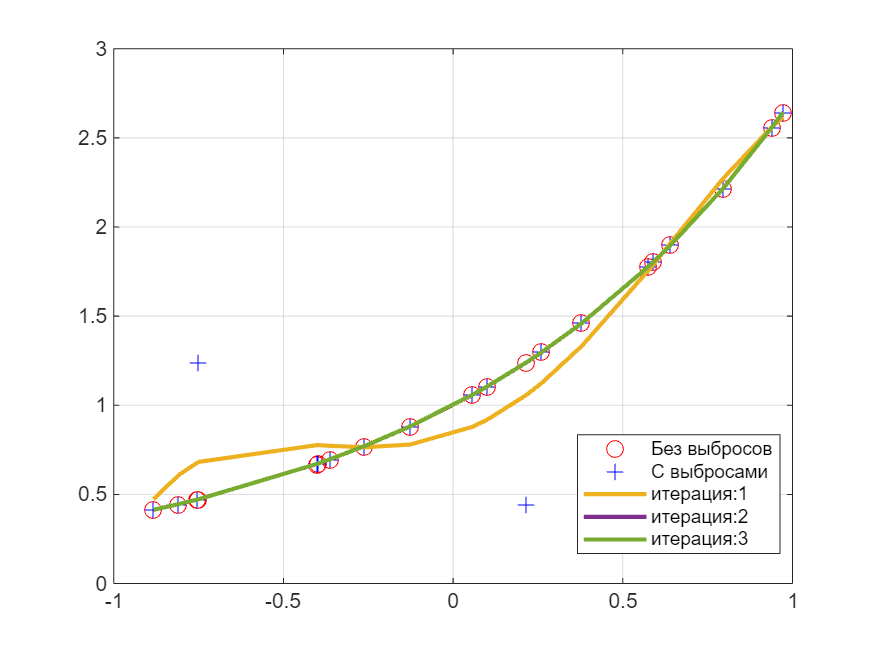

weights = ones(n,1);

ax = get_next_ax();
plot(ax,x,y0,'ro',x,y,'b+',"MarkerSize",8)

% для решения задачи линейной регрессии будет исопльзоваться функция lscov
X = [x.^4,x.^3,x.^2,x,ones(size(x))]; 
% предикторы в матрице в обратном порядке, но это нормально
tb = table();
tb.("no noise")=coeff_no_noise(:);
hold(ax,"on");
for i = 1:iterations % производим несколько итераций
  poly = lscov(X,y,weights)';

  % ошибка регрессии
  resid = polyval(poly,x) - y; % для расчета исопльзуем поливал

  % find the maximum residual to scale the problem
  maxr = max(abs(resid));

  % расс
  weights = exp(-(mu*resid/maxr).^2);
  plot(x,polyval(poly,x),"LineWidth",2)
  tb.("iter "+ string(i))=poly(:);
end
hold(ax,"off")
iterstr = "итерация:" + string(1:iterations);
legend(ax,["Без выбросов", "С выбросами",iterstr ],"Location","best")
grid(ax,"on")

tb

tb = 5×4 table
    no noise    iter 1      iter 2      iter 3 
    ________    _______    ________    ________

    0.046323     -1.104    0.040579    0.041699
     0.17513    0.60905       0.179     0.17873
     0.49761     1.6674     0.50226     0.50073
     0.99844    0.64841     0.99581     0.99606
      1.0001    0.83638     0.99984      1.0003


Видно, что на третьей итерации мы получили очень близкие значения к данным без выбросов.

### Выводы

- Было рассмотрено обоснование метода наименьших квадратов с точки зрения принципа максимального правдоподобия

- Обсудили примеры линейной регрессии с весами (weighted regression)

- Локально-взвешенной регрессии (local-weighted regression) 

- Робастной регрессии (robust regression)

ЛИТЕРАТУРА

1. John D'Errico (2025). Optimization Tips and Tricks (https://www.mathworks.com/matlabcentral/fileexchange/8553-optimization-tips-and-tricks), MATLAB Central File Exchange. Retrieved January 30, 2025.

function M = join_matrix(UL,UR,DL,DR,w,val)
% функция скледивает четыре матрицы в одну, вставляя между ними нул, так,
% чтобы была рамка на картинке
    arguments
        UL
        UR
        DL
        DR
        w = 10
        val = 0;
    end
    r1 = size(UL,1);r2 = size(DL,1);
    c1 = size(DL,2);c2 = size(DR,2);
    M = ones(r1+r2+w,c1+c2+w)*val;
    M(1:r1,1:c1) = UL;
    M(1:r1,(c1+w+1):end)=UR;
    M((r1+w+1):end,1:c1) = DL;
    M((r1+w+1):end,(c1+w+1):end) = DR;   
end
function data = read_bottle_dataset(vars)
        data = struct();
        info = h5info(filename)
        data = h5read("E:\projects\datasets\bases\bottle\bottle.h5",ds) 
        % Open HDF5 file
        % fileID = H5F.open("E:\projects\datasets\bases\bottle\bottle.h5");
        % 
        % data.Datasets(1).Name = "BtlNum";
        % dsID1 = H5D.open(fileID, "/BtlNum");
        % data.Datasets(1).Value = H5D.read(dsID1);
        % 
        % data.Datasets(2).Name = "Depthm";
        % dsID2 = H5D.open(fileID, "/Depthm");
        % data.Datasets(2).Value = H5D.read(dsID2);
end
function rus_name = rus(type)
    possible_types =  ["stand" "legA" "trig" "legP" "custom"];
    possible_rus_names = ["Стандартный базис" "Присоединенные полиномы Лежандра" "Тригонометрический базис" "Полиномы лежандра" "Кастомный"];
    flag = possible_types==type;
    if any(flag)
        rus_name = possible_rus_names(flag);
    else
        rus_name = type;
    end

end
function val = convert_rating_to_number(rating)
    %rating = string(rating);
    switch rating(1)
        case "A"
            val = 7+count(rating,"A");
        case "B"
            val = 8-count(rating,"B");
        case "C"
            val = 4-count(rating,"C");
    end
end
function f = norm_distribution_function(mu,sig)
% возвращает анонимную функцию для нормального распределения
    f =@(x) exp(-(x-mu).^2./(2*sig^2))./(sig*sqrt(2*pi));
end
function [V,s] = vandermatrix(t,P,type,polyprod_function)
arguments
    t double
    P (1,1) double {mustBeInteger,mustBePositive} = 2
    type (1,1) string {mustBeMember(type,["stand" "legA" "trig" "legP" "custom"])} = "stand"
    polyprod_function =[]
end
% создаем матрицу Вандермонда
% type - тип полинома (стандартный базис, полиномы лежандра,
% тригонометрические полиномы)
    t = t(:);
    N = numel(t);
    V = zeros(N,P);
    if ~(type=="custom")
        [Pfun,s] = producing_function(type,t); % возвращаем производящую функцию для колонки матрицы вандермонда
    else
        assert(~isempty(polyprod_function)||~isa(polyprod_function,"function_handle"),"Если выбрана кастомная производящая функция, то нужно ее предоставить")
        s = normalize(t);
        Pfun = @(i)polyprod_function(i,s.x);
    end
    for jj = P:-1:1
        V(:,jj) = Pfun(jj);
    end
end
function dist= make_dist(type,options)
% возращает генератор N случайных чисел, распределенных в соответствии 
% с двух параметрическими распределениями: нормальным, дельта-равномерным,
% Вейбулла и Хи-квадрат
    arguments
        type (1,1) string {mustBeMember(type,["Normal" "Uniform" "Weibull" "Chi2"])}
        options.mu (1,1) =0
        options.sig (1,1)=0
    end
    mu=options.mu;
    sig2=options.sig^2;
    switch type
        case "Normal"
            dist = @(N) mu + sig2*randn([N 1]);
        case "Uniform"
            dist  = @(N)   sqrt(sig2)*(rand([N 1])  -0.5)+ mu;
        case "Weibull"
            dist  = @(N) wblrnd(mu,sqrt(sig2),N,1);
        case "Chi2"
            dist = @(N) (mu + sig2*randn([N 1]).^2);
    end

end
function norm_struct = normalize2(t)
% функция возвращает стурктуру, в которой хранятся данные для нормировки
    if ~issorted(t)
        t = sort(t,"ascend"); 
    end
    tmin = t(1);
    tmax = t(end);
    x = 2.0*((t - tmin) / (tmax - tmin))- 1; 
    norm_struct = struct("tmin",tmin,"tmax",tmax,"x",x); %t,(max(t) - min(t))    
end
function t = denormalize2(s)
    t = 0.5*(s.x + 1.0)*(s.tmax - s.tmin) + s.tmin;
end
function Pn = leg_polyA(i,t) % производящая функция для присоединенных полиномов Лежандра 
    persistent P 
    persistent tleg
    leg_type = 'norm';
    if isempty(tleg)||isempty(P)||(~isequal(t,tleg))
        P = transpose(legendre(i-1,t,leg_type)); % встроенная функция по сути возвращает уже матрицу Вандермонда
        tleg = t;
    end
    if i<=size(P,2)
        Pn = P(:,i);
        return
    end
    P = transpose(legendre(i,t,leg_type));
    tleg = t;
    Pn = P(:,end);
end
function Pn = trig_poly(i,t) % производящая функция для тригонометрических полиномов
    if i==1
        Pn  = ones(size(t));
        return
    end
    if mod(i,2)==0
        Pn = cos(i*t*pi);
    else
        Pn = sin(i*t*pi);
    end
end
function [P,s] = producing_function(type,t)
% функция возвращает производящую функцию для полинома
    s = normalize2(t);
    switch type
        case "stand" % стандартный базис полинома
          P = @(i) s.x.^(i-1);  
        case "legA" % присоединенные полиномы Лежандра
          P = @(i) leg_polyA(i,s.x); 
        case "legP" % полиномы Лежандра
          P = @(i) legendreP(i-1,s.x) ; % стандартная фукнция для полиномов лежандра
        case "trig" % тригонометрический базис
          P = @(i) trig_poly(i,s.x);  

    end
    
end
function [new_ax,fig_handle] = get_next_ax(index, axes_name_value_pairs)
% функция, которая возвращает новые оси на новой фигуре (нужна чтобы
% кратинки в ливскрипте нормально строились)
    arguments
        index = []
        axes_name_value_pairs cell = {}
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);        
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});
        %disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});    
    end
end
function ax = get_named_ax(title_string)
    ax = get_next_ax();
    title(title_string);
end
function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end
function [sampling_volume,tests_number,beta_mat] = sampling_surf_plot(beta,Nmax,Mmax,delta)
        % N
        P = numel(beta);
        sampling_volume = 2:Nmax;
        tests_number = 2:Mmax;
        beta_mat = zeros([Nmax-1,Mmax-1,P]);
        for N=sampling_volume % первый индекс - объем выборки
            x = transpose(linspace(-1,1,N));% столбец координат
            X = vandermatrix(x,P); % матрица вандермонда
            Yo = X*beta;% истинное значение 
            for ii = tests_number% второй индекс - номер теста
                Y = Yo + delta*randn(N,1);
                b_values = X\Y;
                beta_mat(N-1,ii-1,:) = b_values;
            end
        end
end